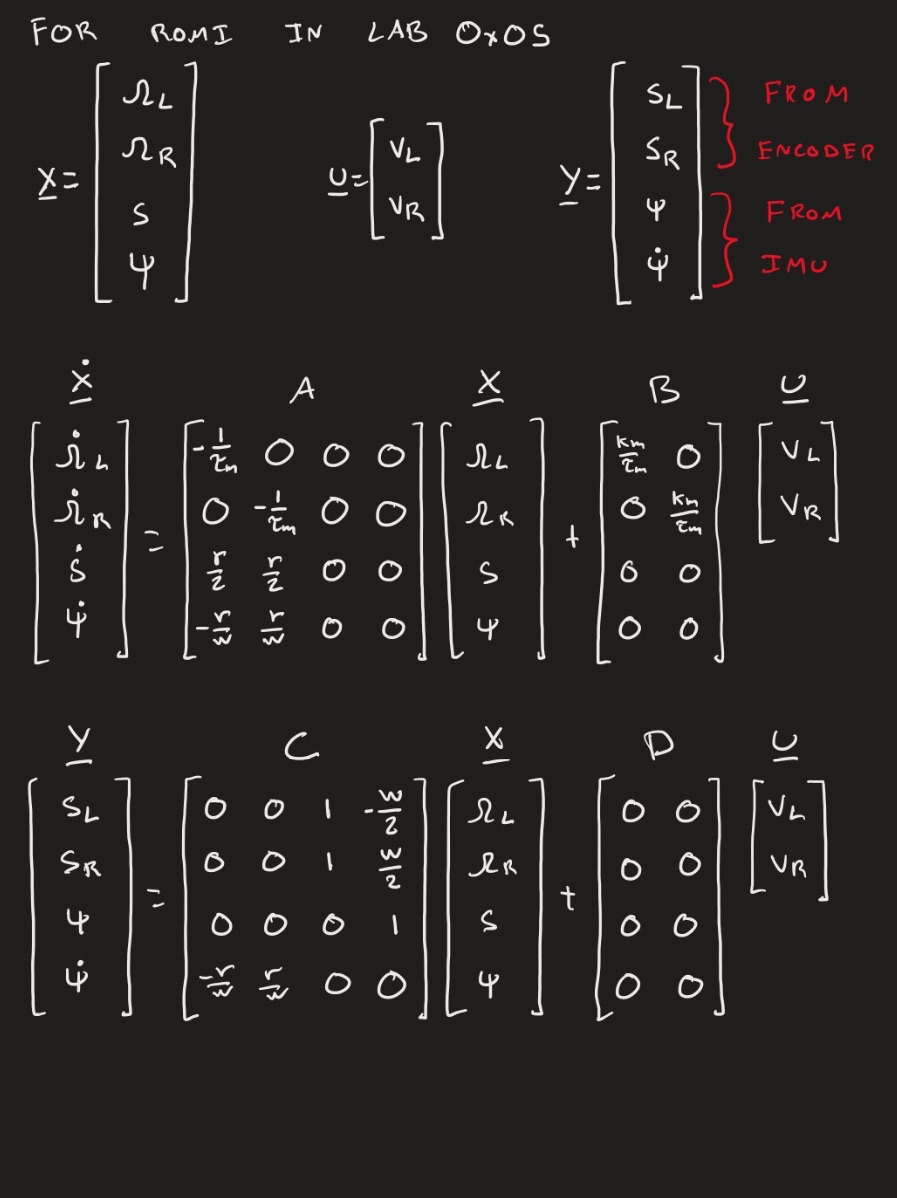


% Electromechanical properties
K      = 250*2*pi/60/4.5;   % Motor Gain [rad/(V*s)]
tau    = 0.1            ;   % Motor Time Constant [s]
r      = 35             ;   % Wheel Radius [mm]
w      = 141            ;   % Width between wheels [mm]

speed_multiplier = 10;
T_s = 0.05 ;% Time step in seconds

A = [-1/tau     0       0   0,
      0         -1/tau  0   0,
      r/2       r/2     0   0,
      -r/w      r/w     0   0];
B = [K/tau  0,
     0      K/tau,
     0      0,
     0      0];
C = [0      0       1   -w/2,
     0      0       1   w/2,
     0      0       0   1,
     -r/w   r/w     0   0];
D = zeros([4,2]);

% Create the state-space model object
sys_ss = ss(A, B, C, D);

% Get the poles of the system model
poles = pole(sys_ss);

% FIND DESIRED POLES




desired_poles = poles.*speed_multiplier;

L = place(A', C', desired_poles)';

A_zero = A - L*C;
B_zero = [B-L*D, L];
new_sys = ss(A_zero, B_zero, C, 0);

disc = c2d(new_sys, T_s);

A_d = disc.A;
B_d = disc.B;

disp(A_d);

    0.4537    0.4470    0.2554   -0.0000
    0.4470    0.4537    0.2554   -0.0000
    0.1738    0.1738    0.1061    0.0000
    0.0000   -0.0000   -0.0000    1.0000



disp(B_d);

    1.6268    1.0490   -0.1277   -0.1277   -0.0000   -1.8006
    1.0490    1.6268   -0.1277   -0.1277    0.0000    1.8006
    0.4079    0.4079    0.4470    0.4470   -0.0000    0.0000
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0500



disp(disc.C);

         0         0    1.0000  -70.5000
         0         0    1.0000   70.5000
         0         0         0    1.0000
   -0.2482    0.2482         0         0

